### Single segment maximally designable base-curve

For a single segment with a target pose and tip-load, find a base-curve that maximizes its valid design space - ie, the base-curve for which the most designs can complete the task.

We will do this for a couple of different target poses and tip-loads.

pose_base = Pose2.hat([0, 0, -pi/2]);

% Here we will assume antagonistic arm
% Placeholder radii and summing matrix
rho_outer = 0.08;
rho_inner = 0.015;
rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

% Antagonistic muscle profiles
f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.15;
N_nodes = 10;

% Combine the design parameters into a struct
struct_design_base = struct();
struct_design_base.mat_A = mat_A;
struct_design_base.l_0 = l_0;
struct_design_base.fs = fs;
struct_design_base.g_0 = g_0;
struct_design_base.rhos = rhos;


#### Test 1a

% Define the target pose and tip-load
pose_target = Pose2.hat([0.1, -0.1, -pi/4]);
Q_tip = [-20; 0; 0];

% Create the design space as a cell array of arm design structs

% Create a uniform sampling of the design space
rho_min = 0.02;
rho_max = 0.15;
l_0_min = 0.5;
l_0_max = 0.6;
N_designs_per_dim = 10;
arm_designs = cell(N_designs_per_dim, N_designs_per_dim);

%
rhos = linspace(rho_min, rho_max, N_designs_per_dim);
l_0s = linspace(l_0_min, l_0_max, N_designs_per_dim);

for i = 1 : N_designs_per_dim
    rhos_i = rhos(i);
    for j = 1 : N_designs_per_dim
        l_0s_j = l_0s(j);
        struct_design_ij = struct_design_base;
        struct_design_ij.rhos  = [rhos_i, 0.02, 0.02, rhos_i]; % Here we just sweep the outer radius
        struct_design_ij.l_0 = l_0s(j);

        arm_designs{i, j} = struct_design_ij;
    end
end

% Optimize the base-curve coefficients such that the most arm designs can
% reach the target pose and loads
f_cost = @(base_curve_coeffs) base_curve_designability(base_curve_coeffs, arm_designs, pose_base, Q_tip);
f_constraint = @(base_curve_coeffs) base_curve_tip_constraint(base_curve_coeffs, pose_target, pose_base, N_nodes);

degree = 3;
initial_coeffs = zeros(2, degree);
initial_coeffs(:, end) = ones(2, 1);
[result_coeffs, f_val] = fmincon(f_cost, initial_coeffs, [], [], [], [], [], [], f_constraint);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


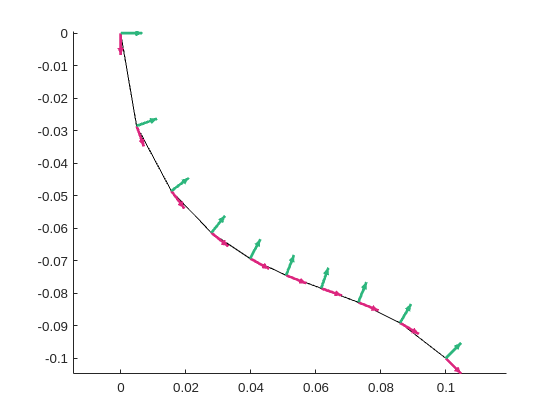

% Plot the base curve that is found
result_poses = integrate_polynomial_curvature(result_coeffs, pose_base, N_nodes);
ax = axes(figure());
plot_poses(result_poses, ax)

function n_valid_designs = base_curve_designability(base_curve_coeffs, arm_designs, pose_base, Q_tip)
    n_valid_designs = 1;
end

function [ineq_constraint, eq_constraint] = base_curve_tip_constraint(base_curve_coeffs, pose_target, pose_base, N_nodes)
    poses = integrate_polynomial_curvature(base_curve_coeffs, pose_base, N_nodes);
    tip_pose = poses(:, :, end);
    
    % Compute the tip pose error aka the residual aka the cost
    rdelta_pose = inv(tip_pose) * pose_target;
    rdelta_twist = Twist2.vee(logm(rdelta_pose));

    K_weights = diag([1, 1, 0.1]);
    eq_constraint = K_weights * rdelta_twist;

    % Enforce constraint that all lengths are positive
    s = linspace(0, 1, N_nodes);
    lengths = polyval(base_curve_coeffs(1, :), s);
    ineq_constraint = -lengths;
end

function poses_out = integrate_polynomial_curvature(base_curve_coeffs, pose_base, N_nodes)
    % Given an 2xC matrix of polynomial coefficients for the lengths and
    % curvatures along the base curve, return the poses integrated at N
    % nodes

    % Preallocate pose matrix
    poses_out = zeros(3, 3, N_nodes);
    poses_out(:, :, 1) = pose_base;
    
    % Compute s and thus the lengths and curvatures
    s = linspace(0, 1, N_nodes);
    ds = 1 / N_nodes;
    lengths = polyval(base_curve_coeffs(1, :), s);
    curvatures = polyval(base_curve_coeffs(2, :), s);

    % Integrate the poses
    for i = 2 : N_nodes
        twist_i = [lengths(i); 0; curvatures(i)];

        delta_pose = Twist2.expm(twist_i * ds);
        poses_out(:, :, i) = poses_out(:, :, i-1) * delta_pose;
    end
end

function design_isvalid = evaluate_designs_fast(rxn_requirement, segment_twists, arm_designs, p_bounds)
    % For each arm design in a cell-array of arm designs, evaluate if they
    % are valid by checking if the tip reaction is attainable for them.
    design_isvalid = cell(size(arm_designs));
    
    for i = 1 : numels(arm_designs)
        design_i = arm_designs(i);
        
        design_isvalid(i) = check_reactions_attainable_fast( ...
            rxn_requirement, ...
            segment_twists, ...
            design_i, ...
            p_bounds...
        );
    end
end

function struct_design_out = make_antagonistic_struct_design(struct_design_base, design_rl)
    struct_design_out = struct_design_base;
    struct_design_out.rhos  = [design_rl(1), 0.02, 0.02, design_rl(1)]; % Here we just sweep the outer radius
    struct_design_out.l_0 = design_rl(2);
end